clear;close;clc
g = 32.2 %ft/s^2

g = 32.2000


U_1 = 266.59; % kts
Theta_1 = deg2rad(1.1);
M_1 = .434;
M_alpha_dot = -.7578;
X_u = -.0138;
X_alpha = 18.2703; % ft/s^2
Z_u = -.1466; % 1/s
Z_alpha = -575.2323;
Z_alpha_dot = -1.8852;
Z_q = -6.1082

Z_q = -6.1082

M_u = 0;
M_alpha = -21.7904;
M_q = -2.8314;
X_q = 0; % by assumption
X_delta_e = 0

X_delta_e = 0

Z_delta_e = -62.6410;
M_delta_e = -23.0586;

Z_1 = 0; % !!! I could not find it in roscom !!

C_prime = [1,0,0,0; 0,(U_1-Z_alpha_dot),0,0; 0,-M_alpha_dot,1,0; 0,0,0,1];
C_prime_inv = inv(C_prime)

C_prime_inv =     1.0000         0         0         0
         0    0.0037         0         0
         0   -0.0028    1.0000         0
         0         0         0    1.0000



A_prime = [...
    X_u, X_alpha, X_q, -g*cos(Theta_1);
    Z_u, Z_alpha, (U_1+Z_q), - g*sin(Theta_1);
    M_u, M_alpha, M_q, 0;
    0, 0, 1, 0;
    ]

A_prime =    -0.0138   18.2703         0  -32.1941
   -0.1466 -575.2323  260.4818   -0.6182
         0  -21.7904   -2.8314         0
         0         0    1.0000         0


B_prime = [X_delta_e; Z_delta_e; M_delta_e; 0]

B_prime =          0
  -62.6410
  -23.0586
         0



A = C_prime\A_prime;
B = C_prime\B_prime;

[W,Lambda] = eig(A)

W =    0.0774 + 0.4762i   0.0774 - 0.4762i   1.0000 + 0.0000i   1.0000 + 0.0000i
   0.0296 + 0.1821i   0.0296 - 0.1821i  -0.0001 - 0.0000i  -0.0001 + 0.0000i
  -0.8409 + 0.0000i  -0.8409 + 0.0000i   0.0004 - 0.0000i   0.0004 + 0.0000i
   0.0882 + 0.1349i   0.0882 - 0.1349i  -0.0003 - 0.0037i  -0.0003 + 0.0037i


Lambda =   -2.8562 + 4.3661i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -2.8562 - 4.3661i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0053 + 0.1184i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0053 - 0.1184i


eigvals = diag(Lambda)

eigvals =   -2.8562 + 4.3661i
  -2.8562 - 4.3661i
  -0.0053 + 0.1184i
  -0.0053 - 0.1184i



for i = 1:length(eigvals)
    eigval = eigvals(i);
    omega = imag(eigval);
    omega_n = norm(eigval);
    sigma = real(eigval);
    xi = -sigma/omega_n;
    fprintf("for the mode with eigenvalue %s: the natural frequency is %g, damping ratio is %g, and damped frequnecy is %g. \n",num2str(eigval),omega_n,xi,abs(omega))
end

for the mode with eigenvalue -2.8562+4.3661i: the natural frequency is 5.21737, damping ratio is 0.54745, and damped frequnecy is 4.3661. 
for the mode with eigenvalue -2.8562-4.3661i: the natural frequency is 5.21737, damping ratio is 0.54745, and damped frequnecy is 4.3661. 
for the mode with eigenvalue -0.0052644+0.1184i: the natural frequency is 0.11852, damping ratio is 0.0444177, and damped frequnecy is 0.118403. 
for the mode with eigenvalue -0.0052644-0.1184i: the natural frequency is 0.11852, damping ratio is 0.0444177, and damped frequnecy is 0.118403. 



fprintf("the eigenvalues of the short period mode is %s and %s ",num2str(eigvals(1)),num2str(eigvals(2)))

the eigenvalues of the short period mode is -2.8562+4.3661i and -2.8562-4.3661i 

fprintf("the eigenvalues of the phugoid mode is %s and %s ",num2str(eigvals(3)),num2str(eigvals(4)))

the eigenvalues of the phugoid mode is -0.0052644+0.1184i and -0.0052644-0.1184i 




C = eye(length(A)); % check if this should be from the given thing or if the given "C" matrix needs to be facotred into A and B
D = [0;0;0;0];
modelss = ss(A,B,C,D)

modelss =
 
  A = 
              x1         x2         x3         x4
   x1    -0.0138      18.27          0     -32.19
   x2  -0.000546     -2.143     0.9702  -0.002302
   x3  0.0004138     -20.17     -3.567   0.001745
   x4          0          0          1          0
 
  B = 
            u1
   x1        0
   x2  -0.2333
   x3   -22.88
   x4        0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.




modeltf = ss2tf(A,B,C,D)

modeltf = 1.0e+03 *

         0         0   -0.0043    0.3158    1.4278
         0   -0.0002   -0.0230   -0.0003   -0.0004
         0   -0.0229   -0.0446   -0.0008    0.0000
         0         0   -0.0229   -0.0446   -0.0008


% TODO: extract the alpha to delta_e ft

startTime = 1;

disp("for short period")

for short period


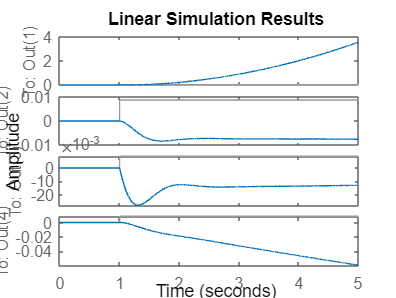

[time, h] = stepGenerator(.001, 5, startTime);
lsim(modelss,1/114.6*h,time)


disp("for phugoid")

for phugoid


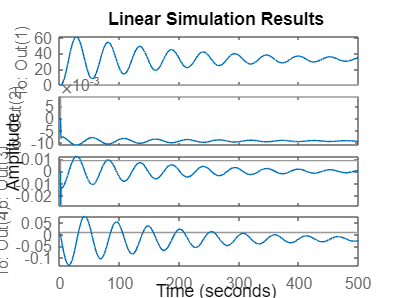

[time, h] = stepGenerator(.01, 500, startTime);
lsim(modelss,1/114.6*h,time)


disp("short period is vissible in the near to a change in our case within 4 seconds of the change is good whereas to see phugoid you must look at larger timescales in our case 500s is pretty good for seeing long period")

short period is vissible in the near to a change in our case within 4 seconds of the change is good whereas to see phugoid you must look at larger timescales in our case 500s is pretty good for seeing long period


%bode(modelss)


## Problem 2

clear;clc;close;
A = [...
    -12.9725, 0, -30.25, 2.1389;
    1, 0, 0, 0;
    -.0029, .1463, -.1872, -.9917;
    -.3591, 0, 9.2719, -.2104;
    ]

A =   -12.9725         0  -30.2500    2.1389
    1.0000         0         0         0
   -0.0029    0.1463   -0.1872   -0.9917
   -0.3591         0    9.2719   -0.2104



B = [75.0517, 4.8177; 0, 0; 0, .102; -3.4118, -10.188]

B =    75.0517    4.8177
         0         0
         0    0.1020
   -3.4118  -10.1880



[W,Lambda] = eig(A)

W =   -0.9967 + 0.0000i  -0.0188 - 0.5707i  -0.0188 + 0.5707i   0.0144 + 0.0000i
   0.0766 + 0.0000i  -0.1763 + 0.0161i  -0.1763 - 0.0161i   0.9893 + 0.0000i
  -0.0031 + 0.0000i   0.0012 + 0.2432i   0.0012 - 0.2432i   0.0041 + 0.0000i
  -0.0257 + 0.0000i   0.7639 + 0.0000i   0.7639 + 0.0000i   0.1451 + 0.0000i


Lambda =  -13.0110 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.1868 + 3.2205i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1868 - 3.2205i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0146 + 0.0000i


eigvals = diag(Lambda)

eigvals =  -13.0110 + 0.0000i
  -0.1868 + 3.2205i
  -0.1868 - 3.2205i
   0.0146 + 0.0000i



for i = 1:length(eigvals)
    eigval = eigvals(i);
    omega = imag(eigval);
    omega_n = norm(eigval);
    sigma = real(eigval);
    xi = -sigma/omega_n;
    fprintf("for the mode with eigenvalue %s: the natural frequency is %g, damping ratio is %g, and damped frequnecy is %g. \n",num2str(eigval),omega_n,xi,abs(omega))
end

for the mode with eigenvalue -13.011: the natural frequency is 13.011, damping ratio is 1, and damped frequnecy is 0. 
for the mode with eigenvalue -0.18681+3.2205i: the natural frequency is 3.22587, damping ratio is 0.0579092, and damped frequnecy is 3.22045. 
for the mode with eigenvalue -0.18681-3.2205i: the natural frequency is 3.22587, damping ratio is 0.0579092, and damped frequnecy is 3.22045. 
for the mode with eigenvalue 0.014552: the natural frequency is 0.0145517, damping ratio is -1, and damped frequnecy is 0. 



fprintf("the eigenvalues of the spiral mode is %s",num2str(eigvals(4)))

the eigenvalues of the spiral mode is 0.014552

fprintf("the eigenvalues of the dutch roll mode is %s and %s ",num2str(eigvals(2)),num2str(eigvals(3)))

the eigenvalues of the dutch roll mode is -0.18681+3.2205i and -0.18681-3.2205i 

fprintf("the eigenvalues of the roll mode is %s",num2str(eigvals(1)))

the eigenvalues of the roll mode is -13.011


C = eye(length(A)); % check if this should be from the given thing or if the given "C" matrix needs to be facotred into A and B
D = [0,0;0,0;0,0;0,0];
modelss = ss(A,B,C,D)

modelss =
 
  A = 
            x1       x2       x3       x4
   x1   -12.97        0   -30.25    2.139
   x2        1        0        0        0
   x3  -0.0029   0.1463  -0.1872  -0.9917
   x4  -0.3591        0    9.272  -0.2104
 
  B = 
           u1      u2
   x1   75.05   4.818
   x2       0       0
   x3       0   0.102
   x4  -3.412  -10.19
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Continuous-time state-space model.




startTime = 1;

disp("for spiral and roll")

for spiral and roll


[time, h] = stepGenerator(.001, 5, startTime);
h = [h;zeros(1,length(time))]

h =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


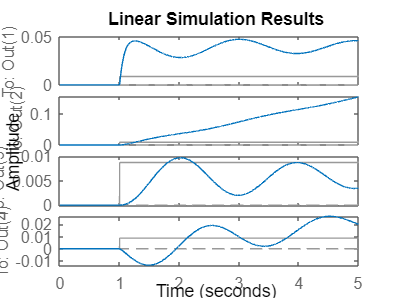

lsim(modelss,1/114.6*h,time)


disp("for dutch roll")

for dutch roll


[time, h] = stepGenerator(.01, 500, startTime);
h = [h;zeros(1,length(time))]

h =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


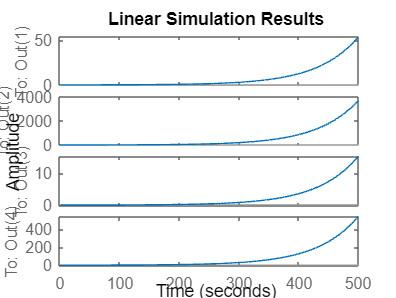

lsim(modelss,1/114.6*h,time)

## problem 3

clear;clc;close;
A1 = [...
    -.0065, 15.9658, 0, -32.1423;
    -.0002, -.5162, .9678, -.0021;
    .001, -1.2483, -.644, -.0002;
    0, 0, 1, 0;
    ]

A1 =    -0.0065   15.9658         0  -32.1423
   -0.0002   -0.5162    0.9678   -0.0021
    0.0010   -1.2483   -0.6440   -0.0002
         0         0    1.0000         0



B1 = [0; -.0373; -1.6897; 0]

B1 =          0
   -0.0373
   -1.6897
         0



[time,u] = doubletGenerator(.001,5,2,.5)
lsim(modelss,deg2rad(.5)*u,time)

function [time, h] = stepGenerator(timestep, endTime, startTime)
time = 0:timestep:endTime;
h = zeros(size(time));
h(startTime/timestep:end) = ones([1,length(h)-startTime/timestep+1]);
end

function [time, u] = doubletGenerator(timestep, endTime, startTime, width)
stopTime = startTime + 2*width;
time = 0:timestep:endTime;
u = zeros(size(time));
u(startTime/timestep:end) = ones([1,stopTime/2/timestep-startTime/timestep+1]);
u(startTime/timestep:end) = -ones([1,stopTime/timestep-stopTime/2/timestep+1]);
end